clc;
clear;
syms theta d alpha a
syms theta_1 theta_2 theta_3

L1 = 0.3

L1 = 0.3000

L2 = 0.25

L2 = 0.2500

L3 = 0.1

L3 = 0.1000


T = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
      sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)            cos(alpha)            d;
          0                 0                     0                 1];

T01 = subs(T, [theta, d, a, alpha], [theta_1  0  L1   0]);
T12 = subs(T, [theta, d, a, alpha], [theta_2  0  L2   0]);
T2E = subs(T, [theta, d, a, alpha], [theta_3  0  L3   0]);


T0E = T01 * T12 * T2E ;
T0E = simplify(T0E)

$$T0E = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \frac{\sigma_{2}}{10}+\frac{\cos\left(\theta_{1}+\theta_{2}\right)}{4}+\frac{3\,\cos\left(\theta_{1}\right)}{10}\\ \sigma_{1} & \sigma_{2} & 0 & \frac{\sigma_{1}}{10}+\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{4}+\frac{3\,\sin\left(\theta_{1}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

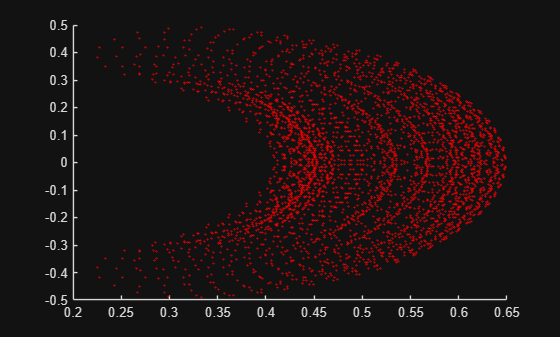


theta_1_range = deg2rad(-30:6:30);
theta_2_range = deg2rad(-45:5:45);
theta_3_range = deg2rad(-170:20:170);
figure 
hold on
for angle_1 = theta_1_range
    for angle_2 = theta_2_range
        for angle_3 = theta_3_range
            temp = subs(T0E, [theta_1, theta_2, theta_3], [angle_1  angle_2  angle_3]);
            plot(temp(1,4),temp(2,4), 'o','MarkerSize',1,'MarkerEdgeColor','red')
        end
    end
end
hold off